[l,ls] = org.all_med_bins('lambda');

Fetched a saved variable: lambda


[s,ss] = org.all_med_bins('signal_variance');

Fetched a saved variable: lambda
Fetched a saved variable: loadings
Fetched a derived variable: signal_variance


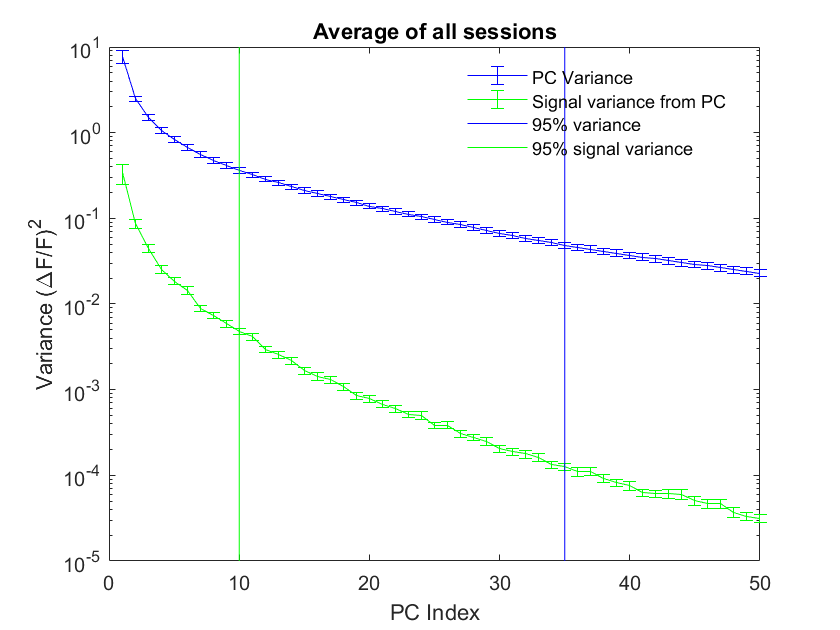

figure;
hl = errorbar(l,ls,'b'); hold on
hs = errorbar(s,ss,'g');
set(gca, 'YScale', 'log');
xlim([0 50]);
v_line = find(cumsum(l)./sum(l) > 0.95, 1);
ll = line([v_line v_line], ylim, 'Color', 'b');
v_line = find(cumsum(s)./sum(s) > 0.95, 1);
ls = line([v_line v_line], ylim, 'Color', 'g');

legend([hl,hs,ll,ls],{'PC Variance', 'Signal variance from PC',...
    '95% variance', '95% signal variance'});
legend box off
legend location best
xlabel 'PC Index'
ylabel 'Variance (\DeltaF/F)^2'
title('Average of all sessions');

[l,ls] = org.all_med_bins('corr_lambda');

Fetched a saved variable: corr_lambda


[s,ss] = org.all_med_bins('corr_signal_variance');

Fetched a saved variable: corr_lambda
Fetched a saved variable: corr_loadings
Fetched a derived variable: corr_signal_variance


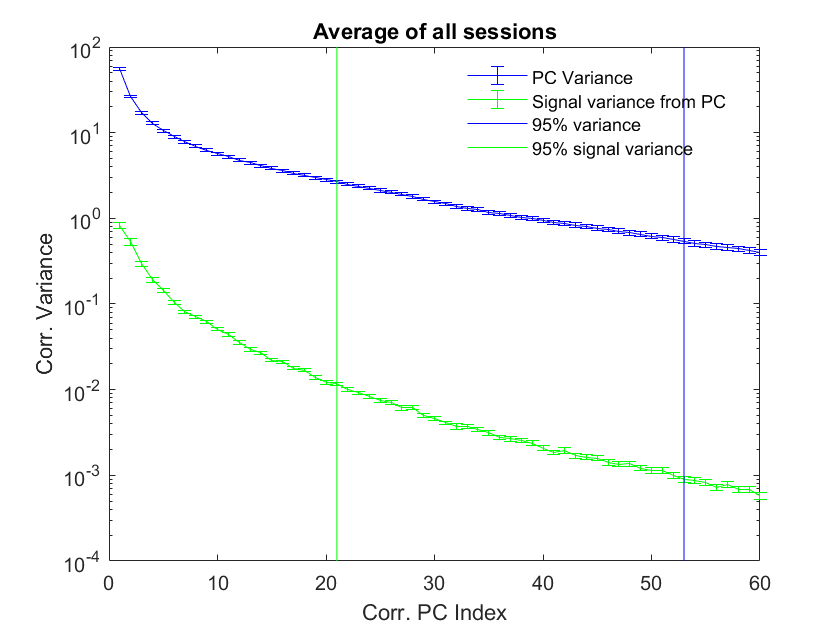

figure;
hl = errorbar(l,ls,'b'); hold on
hs = errorbar(s,ss,'g');
set(gca, 'YScale', 'log');
xlim([0 60]);
v_line = find(cumsum(l)./sum(l) > 0.95, 1);
ll = line([v_line v_line], ylim, 'Color', 'b');
v_line = find(cumsum(s)./sum(s) > 0.95, 1);
ls = line([v_line v_line], ylim, 'Color', 'g');

legend([hl,hs,ll,ls],{'PC Variance', 'Signal variance from PC',...
    '95% variance', '95% signal variance'});
legend box off
legend location best
xlabel 'Corr. PC Index'
ylabel 'Corr. Variance'
title('Average of all sessions');

[ld, lds] = org.all_med_bins('loadings');

Fetched a saved variable: loadings


[ls, lss] = org.all_med_bins('loadings_shuf');

Fetched a saved variable: loadings_shuf


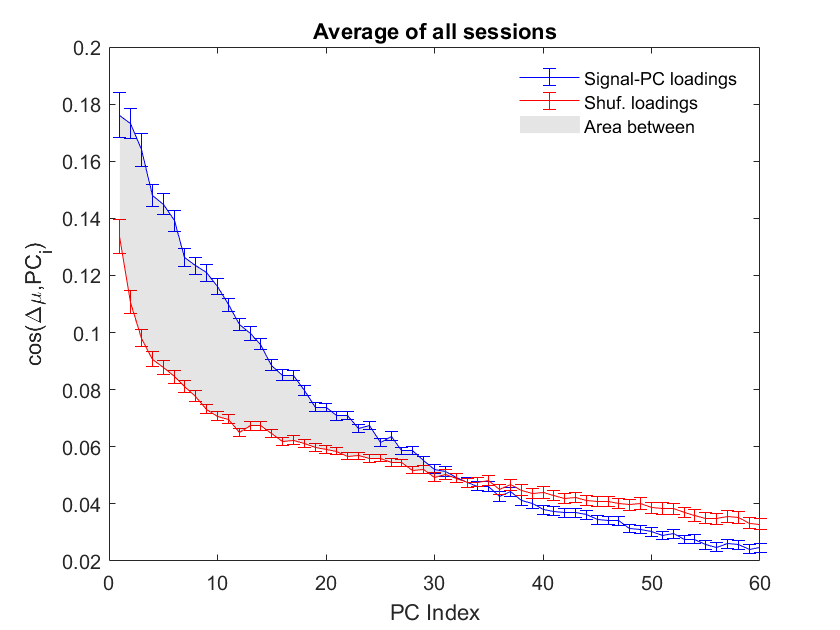


figure;
hl = errorbar(ld, lds, 'b'); hold on
hs = errorbar(ls, lss, 'r');

int = find(ld < ls, 1) - 1;
patch([1:int,int:-1:1], [ld(1:int)',ls(int:-1:1)'], 'k',...
    'EdgeColor', 'none', 'FaceAlpha', 0.1);

xlim([0, 60]);
xlabel 'PC Index'
ylabel 'cos(\Delta\mu,PC_i)'
legend 'Signal-PC loadings' 'Shuf. loadings' 'Area between'
legend boxoff
title 'Average of all sessions'

[ld, lds] = org.all_med_bins('corr_loadings');

Fetched a saved variable: corr_loadings


[ls, lss] = org.all_med_bins('corr_loadings_shuf');

Fetched a saved variable: corr_loadings_shuf


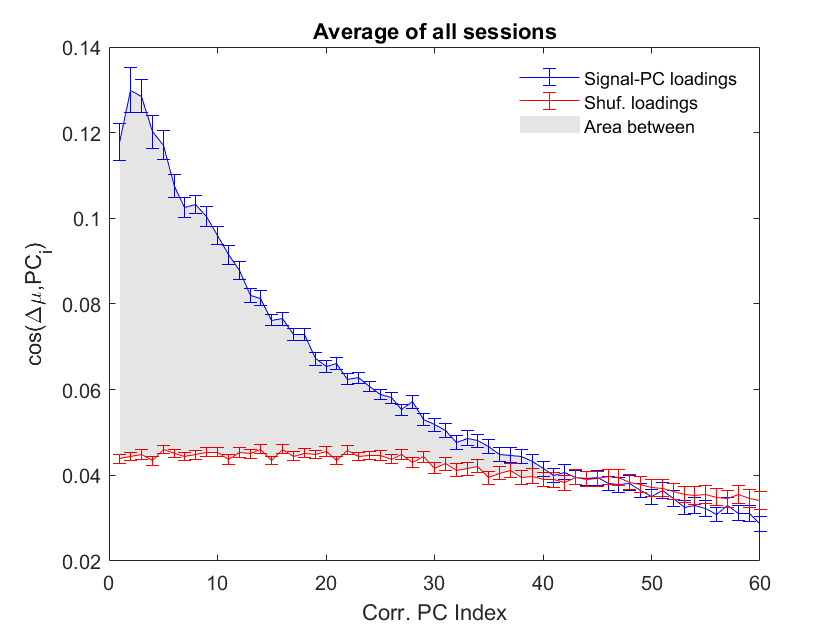


figure;
hl = errorbar(ld, lds, 'b'); hold on
hs = errorbar(ls, lss, 'r');

int = find(ld < ls, 1) - 1;
patch([1:int,int:-1:1], [ld(1:int)',ls(int:-1:1)'], 'k',...
    'EdgeColor', 'none', 'FaceAlpha', 0.1);

xlim([0, 60]);
xlabel 'Corr. PC Index'
ylabel 'cos(\Delta\mu,PC_i)'
legend 'Signal-PC loadings' 'Shuf. loadings' 'Area between'
legend boxoff
title 'Average of all sessions'